# Simulation 3 Companion

## Converting 2nd–Order to 1st–Order (no MATLAB for this section)

The existing ODE solvers like `ode45` are designed to solve 1st order, not 2nd order, ODEs.

**Goal**: Convert $y''+\frac{1}{4}y'+2y = e^{-t}$ with $y(0) = 0$ and $y'(0) = -2$ to a system of **1st** order odes.

**Step 1:** Introduce new variables $y_1$ and $y_2$ to respectively be $y$ and its derivative:


$$y_1 = y$$



$$y_2 = y'$$


This gives us the relationship:


$$(\star): y_1' = y_2$$


**Step 2:** Rewrite the differential equation in terms of $y_1$ and $y_2$ using the substitutions.

$y'' \mapsto y_2'$ and $y' \mapsto y_2$ and $y \mapsto y_1$ 

to get:


$$y''+\frac{1}{4}y'+2y =e^{-t} \mapsto y_2'+\frac{1}{4}y_2+2y_1 = e^{-t}$$


Then isolate $y_2'$ to obtain:


$$(\star\star): y_2' = -2y_1-\frac{1}{4}y_2+e^{-t}$$


**Step 3**: Arrange $(\star)$ and $(\star\star)$  into a system first–order ODEs.


$$\left[\begin{array}{c}y_1'\\ y_2'\end{array}\right] = \left[\begin{array}{c}y_2\\-2y_1-\frac{1}{4}y_2+e^{-t}\end{array}\right]$$


Which we write in vector notation as:


$$\mathbf{y}' = \mathbf{f}(t,\mathbf{y})$$


**Step 4: **Write the initial values in terms of $y_1$ and $y_2$.

We have $y(0) = 0$ and $y'(0) = -2$. So our initial values in terms of $y_1 = y$and $y_2 = y'$ are:


$$\left[\begin{array}{l}y_1 (0)\\y_2(0)\end{array}\right]=\left[\begin{array}{c}0\\-2\end{array}\right]$$


or in vector notation as:


$$\mathbf{y}(0) = \left[\begin{array}{c}0\\-2\end{array}\right]$$


**Done! **

`:)`

## **Solving 2nd-Order ODEs**

Let us continue from where we left off. We successfully converted 2nd–order ODE:

$y''+\frac{1}{4}y'+2y = 0$ with $y(0) = 0$ and $y'(0) = -2$

to the system of 1st–order ODEs:

$\mathbf{y}' = \mathbf{f}(t,\mathbf{y})$ with $\mathbf{y}(0) = \left[\begin{array}{c}0\\-2\end{array}\right]$

where:

$\mathbf{y} = \left[\begin{array}{c}y_1 \\ y_2\end{array}\right]$ and $\mathbf{f}(t,\mathbf{y}) = \left[\begin{array}{c}y_2\\-2y_1-\frac{1}{4}y_2+e^{-t}\end{array}\right]$

**Goal**: Use MATLAB to plot:

- $y(t)$ and $y'(t)$ against $t$ for $0 \leq t \leq 30$

- the **phase plot** $y'(t)$ against $y(t)$ for $0 \leq t \leq 30$

We will use `ode45` once more. Here is a reminder. You should not uncomment anything in this box.

%==========================================================================
%
% ode45: Numerically solves the initial value problem dy/dt = f(t,y) with
% y(0) = y0.
%
%    [t,y] = ode45(f,tspan,y0)
%
%--------------------------------------------------------------------------
%
% ------
% INPUT:
% ------
%   f : (function_handle) dy/dt = f(t,y)
%   tspan = [t0 tf] numerically solves from t0 to tf
%   y0 : (number/vector) initial value/s
%
% ------
% OUTPUT:
% ------
%   t : (column vector) t-values in numerical solution 
%   y : (column vector) values y(t) in numerical solution
%
%==========================================================================

f = function_handle with value:
    @(t,y)[y(2);-2.*y(1)-(1/4).*y(2)+exp(-t)]


Let us define:


$$\mathbf{f}(t,\mathbf{y}) = \left[\begin{array}{c}y_2\\-2y_1-\frac{1}{4}y_2+e^{-t}\end{array}\right]$$


as a function handle for a column–vector of functions applied to the variable `t` and the column vector `y = [y(1);y(2)]`.

*Reminder: uncomment the start of each line and then select Run Section.*

% f = @(t,y) [y(2); -2.*y(1)-(1/4).*y(2)+exp(-t)]

ans =     1.0000
   -1.2500


Let us test this function handle by evaluating it when:

$t = 0$ and $\mathbf{y} = \left[\begin{array}{c}y_1\\y_2\end{array}\right]  = \left[\begin{array}{c}1\\1\end{array}\right]$


$$\left[\begin{array}{c}(1)\\-2(1)-\frac{1}{4}(1)+e^{-0}\end{array}\right] = \left[\begin{array}{c}1\\-1.25\end{array}\right]$$


Run and find out.

% f(0,[1,1])

tspan =      0    30


Things seem to be in working order. Next we define the span $0 \leq t \leq 30$.

% tspan = [0 30]

y0 =      0
    -2


And next we define the initial values column vector: 


$$\mathbf{y}(0) = \left[\begin{array}{c}0\\-2\end{array}\right]$$


% y0 = [0;-2]

t =          0
    0.0000
    0.0001
    0.0001
    0.0001
    0.0002
    0.0004
    0.0005
    0.0006
    0.0012
    0.0019
    0.0025
    0.0031
    0.0063
    0.0094


y =          0   -2.0000
   -0.0001   -2.0000
   -0.0001   -1.9999
   -0.0002   -1.9999
   -0.0002   -1.9998
   -0.0005   -1.9997
   -0.0007   -1.9995
   -0.0010   -1.9993
   -0.0012   -1.9991
   -0.0025   -1.9982
   -0.0037   -1.9972
   -0.0050   -1.9963
   -0.0062   -1.9953
   -0.0125   -1.9906
   -0.0187   -1.9858


We are ready to solve the differential equation.

% [t,y] = ode45(f,tspan,y0)

Notice that `y` has two columns. The first column `y(:,1)` are the values $y_1(t) = y(t)$ and the second column `y(:,2)` are the values $y_2(t) = y'(t)$.

Let us now complete the plotting tasks each in their own figure window.

- $y(t)$ and $y'(t)$ against $t$ for $0 \leq t \leq 30$

- the **phase plot** $y'(t)$ against $y(t)$ for $0 \leq t \leq 30$

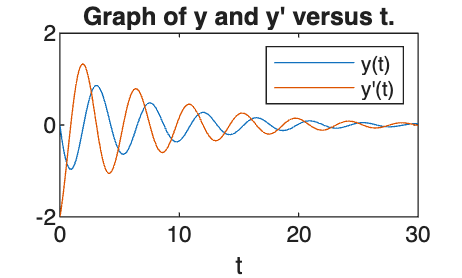

% % Task 1.
% figure % new figure window
% plot(t,y(:,1)) % plot y(t) against t
% hold on 
% plot(t,y(:,2)) % plot y'(t) against t
% xlabel("t") % label the x-axis as t

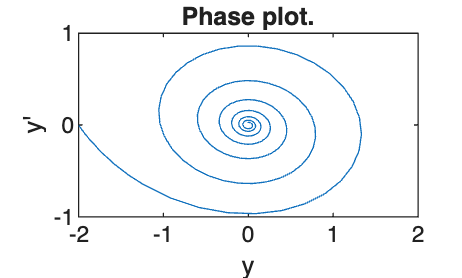

% legend("y(t)","y'(t)") % label the graphs in the order they were plotted
% title("Graph of y and y' versus t.") % indicate that this is y and y' versus t
% 
% % Task 2.
% figure % new figure window
% plot(y(:,2),y(:,1)) % plot y'(t) against y(t)
% xlabel("y") % label the x-axis as y

% ylabel("y'") % label the y-axis as y'
% title("Phase plot.") % indicate that this is the phase plot